load('data\\shimizu_25kg.mat');
load('data\\shimizu_5kg.mat');
load('data\\shimizu_75kg.mat');
load('data\\shimizu_10kg.mat');
load('data\\shimizu_MVC100.mat');
load('data\\shimizu_5kg_reversed.mat');
load('data\\shimizu_udetate_slow.mat');
load('data\\shimizu_udetate_fast.mat');
load('data\\maruyama_25kg.mat');
load('data\\maruyama_5kg.mat');
load('data\\maruyama_75kg.mat');
load('data\\maruyama_10kg.mat');
load('data\\maruyama_MVC100.mat');
load('data\\maruyama_udetate_slow.mat');
load('data\\maruyama_udetate_fast.mat');
time=shimizu_25kg.Time;

s_weight=[shimizu_25kg; shimizu_5kg; shimizu_75kg; shimizu_10kg];
s_mvc=shimizu_MVC100;
s_ude=[shimizu_udetate_slow; shimizu_udetate_fast];


function ret=plot_and_get(raw, rmsfreq)
    
    data=raw.Dev3_ai1;
    
    fs=1000;
    dt=1/fs;
    n=length(data);
    t=raw.Time;
    
    for i = 1:9
        d = designfilt('bandstopiir','FilterOrder',2, ...
                   'HalfPowerFrequency1',50*i-1,'HalfPowerFrequency2',50*i+1, ...
                   'DesignMethod','butter','SampleRate',fs);
        data=filter(d,data);
    end
    
    bpFilt = designfilt('bandpassiir','FilterOrder',20, ...
             'HalfPowerFrequency1',5,'HalfPowerFrequency2',500, ...
             'SampleRate',fs);
    data = filter(bpFilt,data);
    
    [psdx,f1] = periodogram(data,rectwin(n),n,fs,'ConfidenceLevel',0.95);
    
    t_rms=t(1:rmsfreq:end);
    emg_rms=zeros(n/rmsfreq,1);
    mfreq_rms=zeros(n/rmsfreq,1);
    for i=1:n/rmsfreq
        emg_tmp=data((i-1)*rmsfreq+1:i*rmsfreq);
        emg_rms(i,1)=rms(emg_tmp);
        [psdx_tmp,ftmp] = periodogram(emg_tmp,rectwin(length(emg_tmp)),length(emg_tmp),fs,'ConfidenceLevel',0.95);
        mfreq_rms(i)=medfreq(psdx_tmp,fs);
    end
    mfreq=medfreq(psdx,fs)
    
    plot(t_rms, emg_rms, "Color", '#4DBEEE')
    %plot(t_rms, mfreq_rms, "Color", '#4DBEEE')
    t_rms=seconds(t(1:rmsfreq:end-30*fs+1));
    emg_rms=emg_rms(15*fs/rmsfreq:end-15*fs/rmsfreq);
    ret=polyfit(t_rms,emg_rms,1)
end

function ret=get_mvc(raw)
    data=raw.Dev3_ai1;
    
    fs=1000;
    dt=1/fs;
    n=length(data);
    t=raw.Time;
    
    for i = 1:9
        d = designfilt('bandstopiir','FilterOrder',2, ...
                   'HalfPowerFrequency1',50*i-1,'HalfPowerFrequency2',50*i+1, ...
                   'DesignMethod','butter','SampleRate',fs);
        data=filter(d,data);
    end
    
    bpFilt = designfilt('bandpassiir','FilterOrder',20, ...
             'HalfPowerFrequency1',5,'HalfPowerFrequency2',500, ...
             'SampleRate',fs);
    data = filter(bpFilt,data);
    
    rmsfreq=500;
    t_rms=t(1:rmsfreq:end);
    emg_rms=zeros(n/rmsfreq,1);
    mfreq_rms=zeros(n/rmsfreq,1);
    for i=1:n/rmsfreq
        emg_tmp=data((i-1)*rmsfreq+1:i*rmsfreq);
        emg_rms(i,1)=rms(emg_tmp);
        [psdx_tmp,ftmp] = periodogram(emg_tmp,rectwin(length(emg_tmp)),length(emg_tmp),fs,'ConfidenceLevel',0.95);
        mfreq_rms(i)=medfreq(psdx_tmp,fs);
    end
    
    plot(t_rms, emg_rms, "Color", '#4DBEEE')
    ret=mean(emg_rms(10*fs/rmsfreq:20*fs/rmsfreq));
end

'shimizu_mvc'

ans = 'shimizu_mvc'

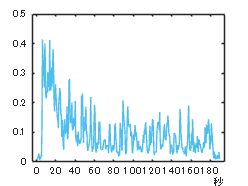

mvc = 0.2707

smvc=get_mvc(shimizu_MVC100)

'maruyama_mvc'

ans = 'maruyama_mvc'

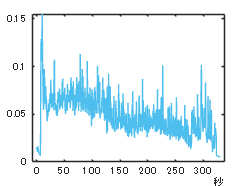

mvc = 0.0768

mmvc=get_mvc(maruyama_MVC100)

mfreq = 0.6343

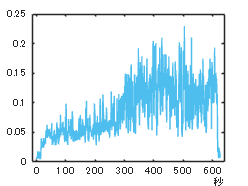

ret =     0.0002    0.0377


'shimizu'
pols=zeros(4,2);
pols(1,:)=plot_and_get(shimizu_25kg,500);

mfreq = 0.7194

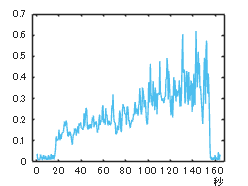

ret =     0.0021    0.0997


pols(2,:)=plot_and_get(shimizu_5kg,500);

mfreq = 2.1591

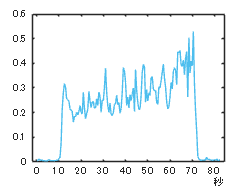

ret =     0.0032    0.1907


pols(3,:)=plot_and_get(shimizu_75kg,500);

mfreq = 1.0528

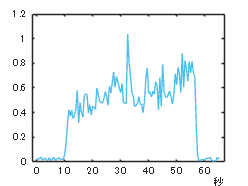

ret =     0.0036    0.4883


pols(4,:)=plot_and_get(shimizu_10kg,500);


pols

pols =     0.0002    0.0377
    0.0021    0.0997
    0.0032    0.1907
    0.0036    0.4883


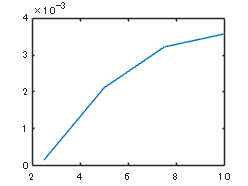

plot([2.5; 5; 7.5; 10],pols(:,1))

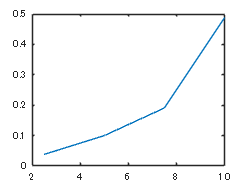

plot([2.5; 5; 7.5; 10],pols(:,2))

tire=polyfit([2.5; 5; 7.5; 10],pols(:,1),2)

tire =    -0.0001    0.0013   -0.0026


power=polyfit([2.5; 5; 7.5; 10],pols(:,2),2)

power =     0.0094   -0.0601    0.1378


'maruyama'

ans = 'maruyama'

mfreq = 0.7093

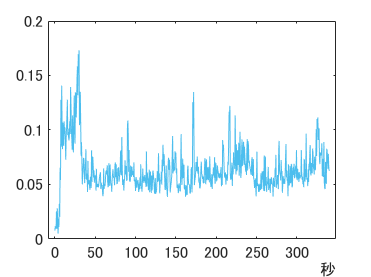

ret =    -0.0000    0.0699


pols=zeros(4,2);
pols(1,:)=plot_and_get(maruyama_25kg,500);

mfreq = 1.4707

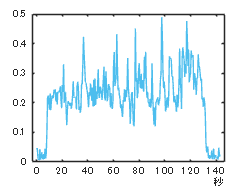

ret =     0.0007    0.2142


pols(2,:)=plot_and_get(maruyama_5kg,500);

mfreq = 1.4234

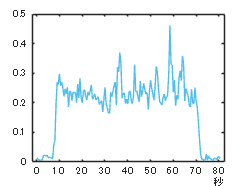

ret =     0.0010    0.2155


pols(3,:)=plot_and_get(maruyama_75kg,500);

mfreq = 1.5302

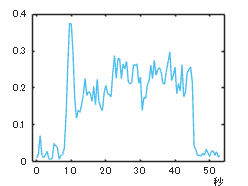

ret =     0.0026    0.1875


pols(4,:)=plot_and_get(maruyama_10kg,500);


pols

pols =    -0.0000    0.0699
    0.0007    0.2142
    0.0010    0.2155
    0.0026    0.1875


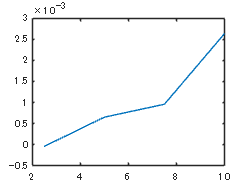

plot([2.5; 5; 7.5; 10],pols(:,1))

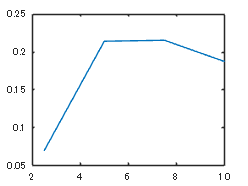

plot([2.5; 5; 7.5; 10],pols(:,2))

tire=polyfit([2.5; 5; 7.5; 10],pols(:,1),2)

tire = 1.0e-03 *

    0.0393   -0.1579    0.1963


power=polyfit([2.5; 5; 7.5; 10],pols(:,2),2)

power =    -0.0069    0.1004   -0.1323


'reverse'

ans = 'reverse'

mfreq = 0.9417

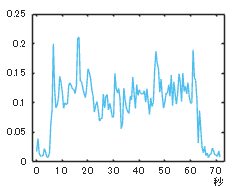

ret =    -0.0000    0.1160


ret =    -0.0000    0.1160


ret=plot_and_get(shimizu_5kg_reversed,500)

'udetate'

ans = 'udetate'

mfreq = 8.9806

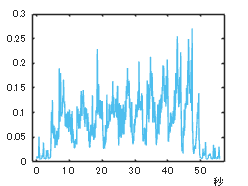

ret =     0.0014    0.0790


plot_and_get(shimizu_udetate_slow,100);

mfreq = 4.3326

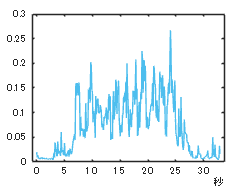

ret =     0.0189    0.0825


plot_and_get(shimizu_udetate_fast,100);